% exact same code as 3d
% setting
folder = 'C:\Users\bear\Desktop\figure 4\2d';
filename = 'liver_2d_all_planes.csv';
outname = 'liver_2d_all_planes_final.csv';

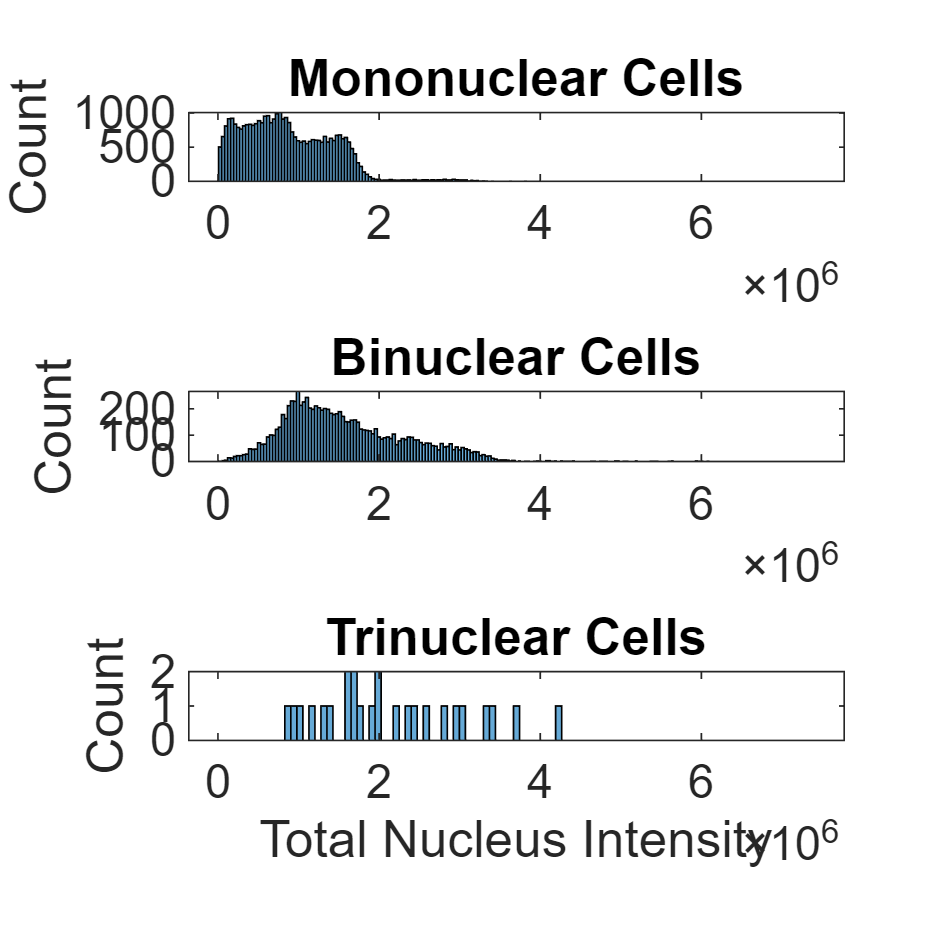

table = readtable(fullfile(folder, filename));
%threshold_m = [2e5, 8e5, 16e5, 32e5];
%threshold_b = [4e5, 16e5, 32e5];
%threshold_t = [6e5, 24e5];

figure('Position', [100, 100, 600, 600]);
fontsize = 14;

% Define bins for mono/binuclear
all_intensities = table.TotalNucleusIntensity;
nbins = 200;  
edges = linspace(min(all_intensities), max(all_intensities), nbins);

% Define same / fewer bins for multinuclear
nbins_tri = 100;  
edges_tri = linspace(min(all_intensities), max(all_intensities), nbins_tri);

% Plot in three separate subplots
subplot(3,1,1)
histogram(table.TotalNucleusIntensity(table.NumNuclei == 1), edges)
title('Mononuclear Cells')
ylabel('Count')
hold on
%for i = 1:length(threshold_m)
%    xline(threshold_m(i), ':', 'Color', 'r', 'LineWidth', 1.5)
%end
hold off
set(gca, 'FontSize', fontsize);

subplot(3,1,2)
histogram(table.TotalNucleusIntensity(table.NumNuclei == 2), edges)
title('Binuclear Cells')
ylabel('Count')
hold on
%for i = 1:length(threshold_b)
%    xline(threshold_b(i), ':', 'Color', 'r', 'LineWidth', 1.5)
%end
hold off
set(gca, 'FontSize', fontsize);

subplot(3,1,3)
histogram(table.TotalNucleusIntensity(table.NumNuclei == 3), edges_tri)
title('Trinuclear Cells')
xlabel('Total Nucleus Intensity')
ylabel('Count')
hold on
%for i = 1:length(threshold_t)
%    xline(threshold_t(i), ':', 'Color', 'r', 'LineWidth', 1.5)
%end
hold off
set(gca, 'FontSize', fontsize);

saveas(gcf, fullfile(folder, 'polyploidy_2d.png'));

table = readtable(fullfile(folder, filename));

% Define the desired order for each nuclear type
total_cells = height(table);
fprintf('Total: %d', total_cells);

Total: 44506


mono_data = table.ID(table.NumNuclei == 1);
mono_total = length(mono_data);
fprintf('Mononuclear: %d (%.1f%% of all cells)', mono_total, 100 * mono_total / total_cells);

Mononuclear: 35219 (79.1% of all cells)


bi_data = table.ID(table.NumNuclei == 2);
bi_total = length(bi_data);
fprintf('Binuclear: %d (%.1f%% of all cells)', bi_total, 100 * bi_total / total_cells);

Binuclear: 9262 (20.8% of all cells)


tri_data = table.ID(table.NumNuclei == 3);
tri_total = length(tri_data);
fprintf('Trinuclear: %d (%.2f%% of all cells)', tri_total, 100 * tri_total / total_cells);

Trinuclear: 25 (0.06% of all cells)

% the below stuff bye bye...
table = readtable(fullfile(folder, filename));
writetable(table, fullfile(folder, outname));

%{
% Create new column as categorical
table = readtable(fullfile(folder, filename));
table.NuclearPloidy = strings(height(table), 1);

% For mononuclear cells
mono_idx = table.NumNuclei == 1;
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity < threshold_m(1)) = 'small';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(1) & table.TotalNucleusIntensity < threshold_m(2)) = 'm2n';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(2) & table.TotalNucleusIntensity < threshold_m(3)) = 'm4n';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(3) & table.TotalNucleusIntensity < threshold_m(4)) = 'm8n';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(4)) = 'm>8n';

% For binuclear cells
bi_idx = table.NumNuclei == 2;
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity < threshold_b(1)) = 'small';
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity >= threshold_b(1) & table.TotalNucleusIntensity < threshold_b(2)) = 'b2n';
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity >= threshold_b(2) & table.TotalNucleusIntensity < threshold_b(3)) = 'b4n';
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity >= threshold_b(3)) = 'b>4n';

% For trinuclear cells
tri_idx = table.NumNuclei == 3;
table.NuclearPloidy(tri_idx & table.TotalNucleusIntensity < threshold_t(1)) = 'small';
table.NuclearPloidy(tri_idx & table.TotalNucleusIntensity >= threshold_t(1) & table.TotalNucleusIntensity < threshold_t(2)) = 't2n';
table.NuclearPloidy(tri_idx & table.TotalNucleusIntensity >= threshold_t(2)) = 't>2n';

% Define the desired order for each nuclear type
disp('Mononuclear classifications:');
mono_order = {'small', 'm2n', 'm4n', 'm8n', 'm>8n'};
mono_data = table.NuclearPloidy(table.NumNuclei == 1);
for cat = mono_order
    count = sum(mono_data == cat{1});
    percent = 100 * count / length(mono_data);
    fprintf('%s: %d (%.1f%%)\n', cat{1}, count, percent);
end

disp('Binuclear classifications:');
bi_order = {'small', 'b2n', 'b4n', 'b>4n'};
bi_data = table.NuclearPloidy(table.NumNuclei == 2);
for cat = bi_order
    count = sum(bi_data == cat{1});
    percent = 100 * count / length(bi_data);
    fprintf('%s: %d (%.1f%%)\n', cat{1}, count, percent);
end

disp('Trinuclear classifications:');
tri_order = {'small', 't2n', 't>2n'};
tri_data = table.NuclearPloidy(table.NumNuclei == 3);
for cat = tri_order
    count = sum(tri_data == cat{1});
    percent = 100 * count / length(tri_data);
    fprintf('%s: %d (%.1f%%)\n', cat{1}, count, percent);
end

writetable(table, fullfile(folder, outname));
%}

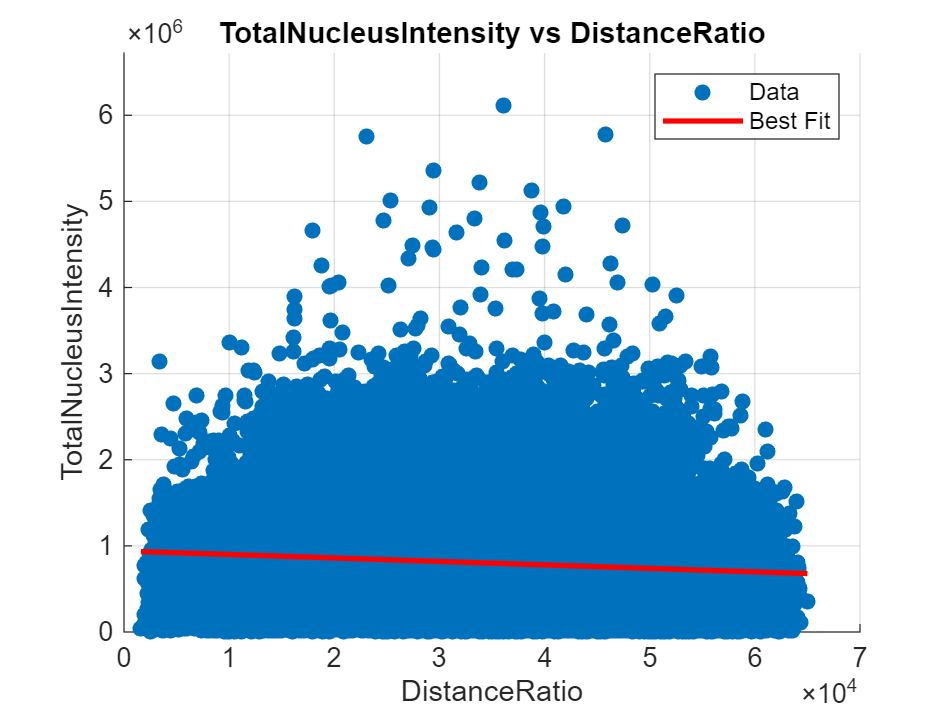

% ID, DistanceRatio, Volume, eccentricity
% TotalNucleusVolume, TotalNucleusIntensity, NumNuclei, NuclearPloidy
table = readtable(fullfile(folder, outname));

% Continuous variables
columns1 = [6, 2];
plot_scatter(table, columns1);

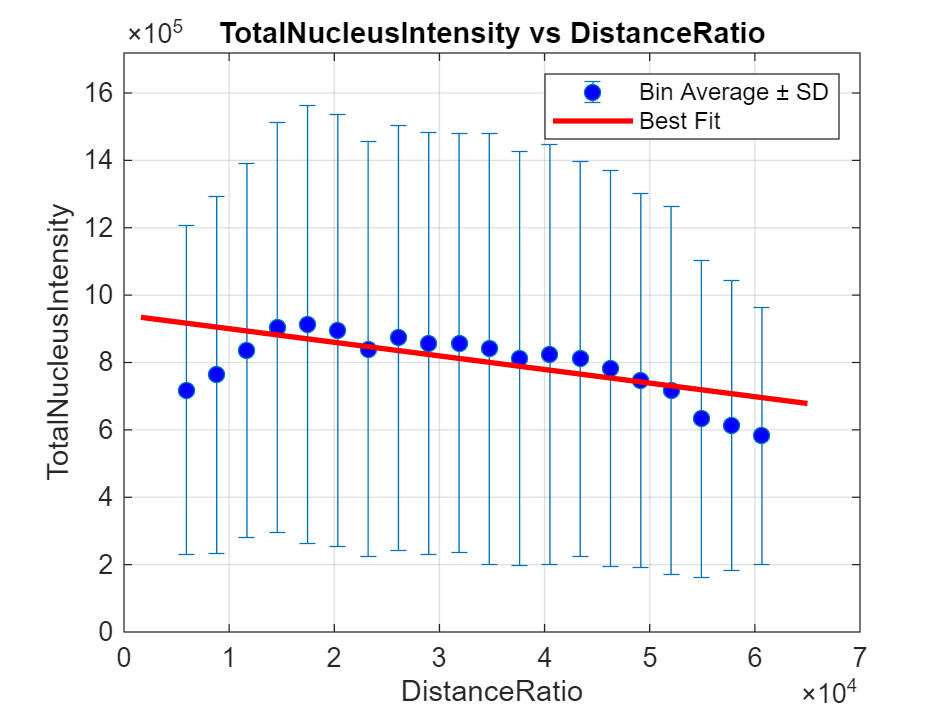

plot_error_bars(table, columns1, 20);

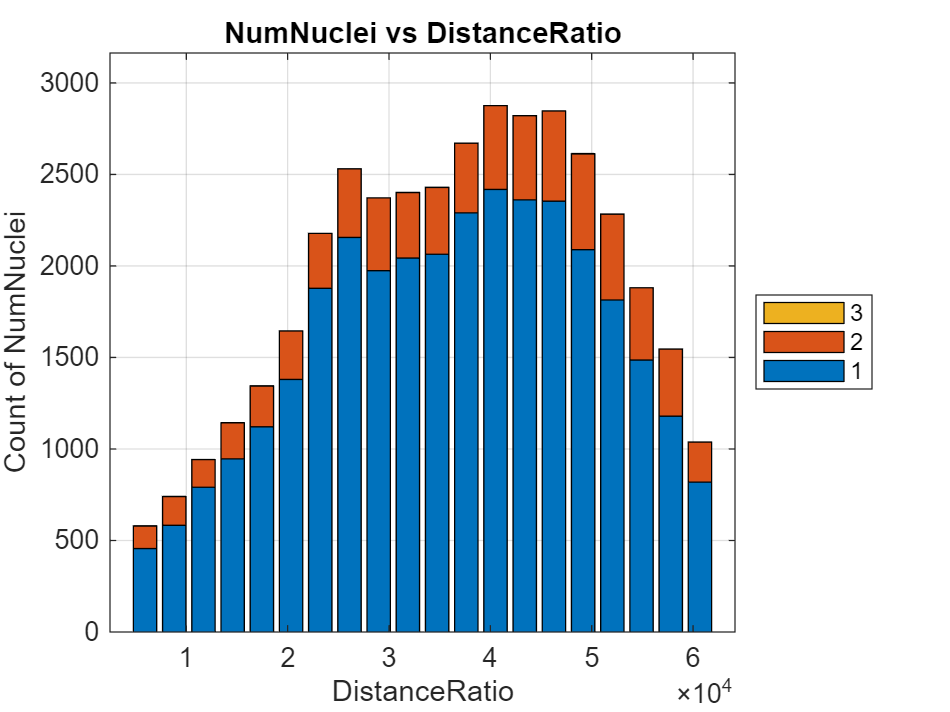


% Categorical variables
columns2 = [7, 2];
plot_stacked_counts(table, columns2, 20);

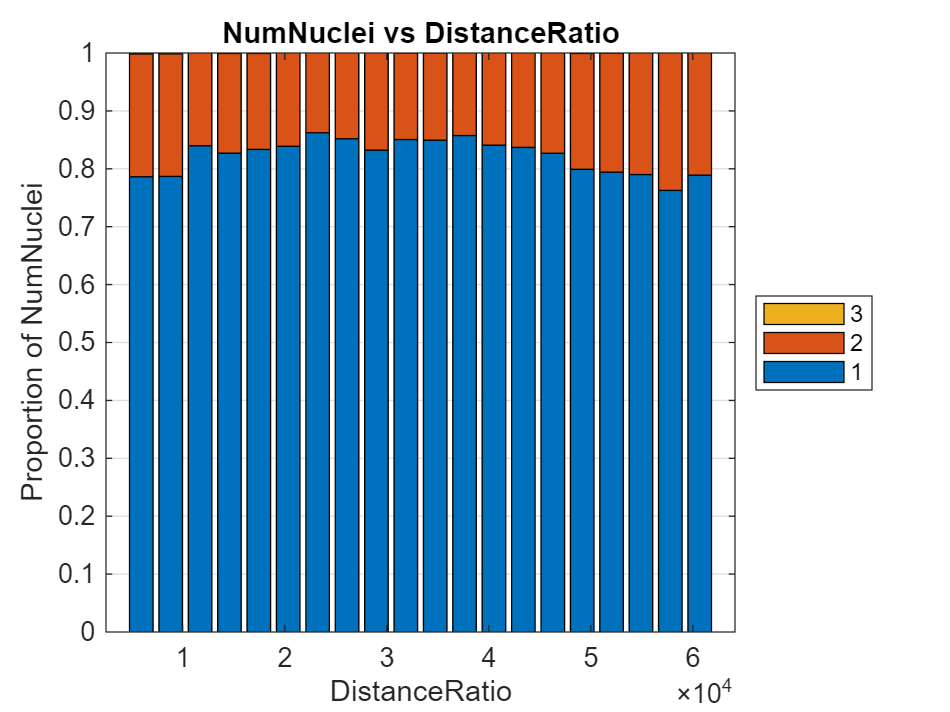

plot_stacked_proportions(table, columns2, 20);